clear all;
filelist = ["data_04-Mar-2025_10.mat" "data_21-Mar-2025_09-26-10.mat" "data_21-Mar-2025_09-28-59.mat" "data_21-Mar-2025_09-32-07.mat" "data_21-Mar-2025_09-34-30.mat" "data_21-Mar-2025_09-37-20.mat" "data_21-Mar-2025_09-42-10.mat" "data_21-Mar-2025_09-43-30.mat" "data_21-Mar-2025_09-51-00.mat" "data_21-Mar-2025_09-52-42.mat" "data_21-Mar-2025_09-55-40.mat" "data_21-Mar-2025_10 motor0 19 to 31 rads.mat" "data_21-Mar-2025_10 motor1 19 to 31 rads.mat" "data_21-Mar-2025_10-02-58.mat" "data_21-Mar-2025_10-09-11.mat" "data_21-Mar-2025_10-10-37.mat" "data_21-Mar-2025_10-12-01.mat" "data_21-Mar-2025_10-17-54.mat" "data_21-Mar-2025_10-21-14.mat" "data_21-Mar-2025_10-24-43.mat" "data_21-Mar-2025_10-29-46.mat" "data_21-Mar-2025_10-36-06.mat" "data_21-Mar-2025_10deazone mot1 pos.mat" "data_21-Mar-2025_20 deadzone mot0 pos.mat" "data_21-Mar-2025_20 deadzone mot1 neg.mat" "data_21-Mar-2025_20 deadzone motor0 neg.mat" "data_21-Mar-2025_20 motor0 1v.mat" "data_21-Mar-2025_20 motor0 31 to 40 rads 1.5v.mat" "data_21-Mar-2025_20 motor01together interrupted.mat" "data_21-Mar-2025_20 motor1 1v.mat" "data_21-Mar-2025_20 motor1 31 to 40rads 1.5v.mat"]

filelist = 1×31 string array
    "data_04-Mar-2025_10.mat"    "data_21-Mar-2025_09-26-10.mat"    "data_21-Mar-2025_09-28-59.mat"    "data_21-Mar-2025_09-32-07.mat"    "data_21-Mar-2025_09-34-30.mat"    "data_21-Mar-2025_09-37-20.mat"    "data_21-Mar-2025_09-42-10.mat"    "data_21-Mar-2025_09-43-30.mat"    "data_21-Mar-2025_09-51-00.mat"    "data_21-Mar-2025_09-52-42.mat"    "data_21-Mar-2025_09-55-40.mat"    "data_21-Mar-2025_10 motor0 19 to 31 rads.mat"    "data_21-Mar-2025_10 motor1 19 to 31 rads.mat"    "data_21-Mar-2025_10-02-58.mat"    "data_21-Mar-2025_10-09-11.mat"    "data_21-Mar-2025_10-10-37.mat"    "data_21-Mar-2025_10-12-01.mat"    "data_21-Mar-2025_10-17-54.mat"    "data_21-Mar-2025_10-21-14.mat"    "data_21-Mar-2025_10-24-43.mat"    "data_21-Mar-2025_10-29-46.mat"    "data_21-Mar-2025_10-36-06.mat"    "data_21-Mar-2025_10deazone mot1 pos.mat"    "data_21-Mar-2025_20 deadzone mot0 pos.mat"    "data_21-Mar-2025_20 deadzone mot1 neg.mat"    "data_21-Mar-2025_20 deadzone moto


file = "lab3/data/" + filelist(1)

file = "lab3/data/data_04-Mar-2025_10.mat"


load(file,"data")

fs=500;
ts = 1/fs;


## Divide time to see what frequencies happen at which time:

motorID = 0;
time = data(1,:);
y = data(2+motorID,:)*pi/2048;
u = data(4+motorID,:);
om = data(6,:);


slices = sliceTimeSeries(time,om);


wrong_exp = [ 0 5.5 13 17.5 18 20];



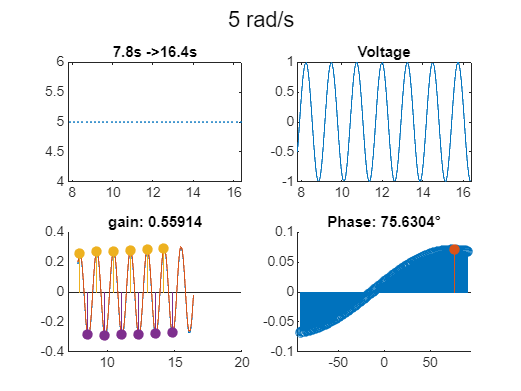

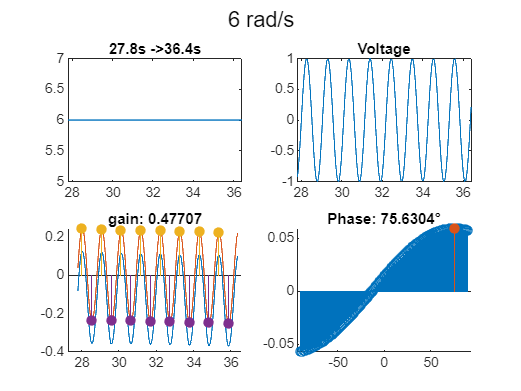

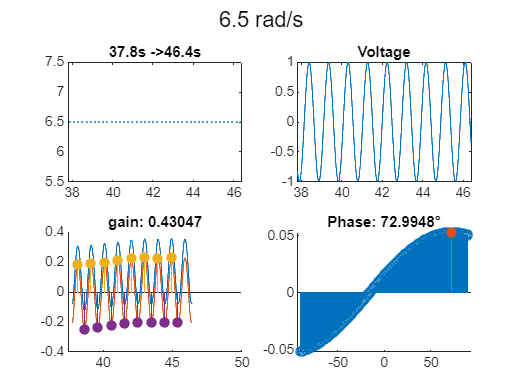

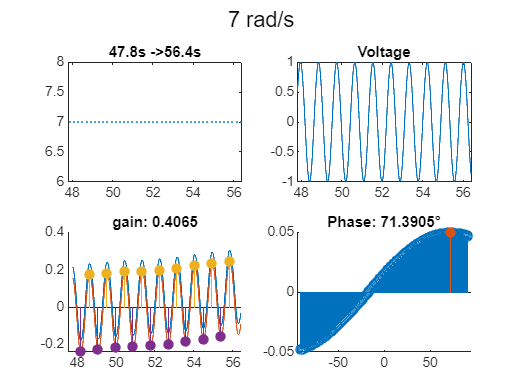

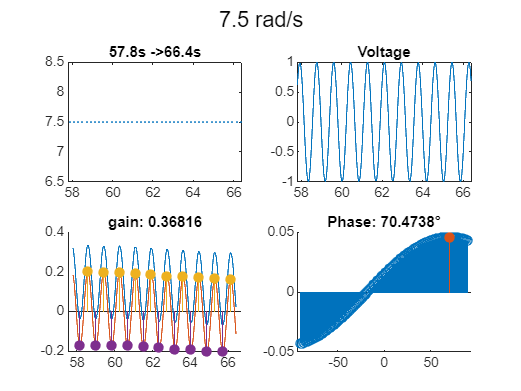

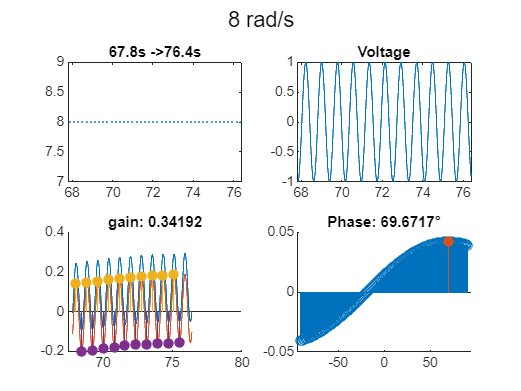

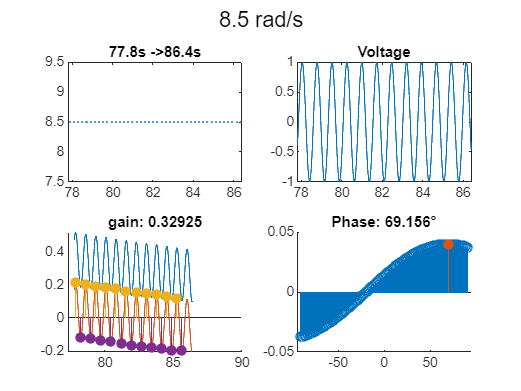

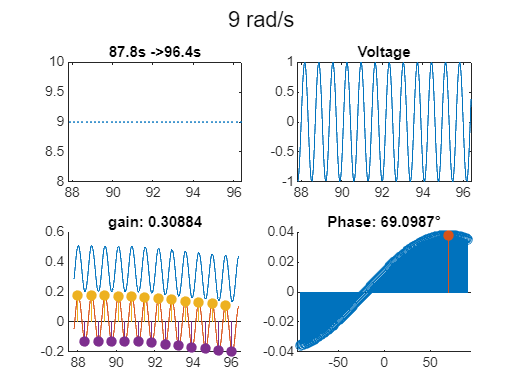

% for i = 2:2
for i = 1:size(slices,2)
    omega = slices{i}.f;
    k = find(wrong_exp==omega);
if size(k,2)~=0 % it's one of the wrong experiments
    slices{i}.phase = NaN;
    slices{i}.gain = NaN;
else
    focus = slices{i};

    t_start_idx = time2index(focus.t_start);
    t_end_idx = time2index(focus.t_end);
   

    t_focus= time(t_start_idx:t_end_idx);
    om_focus= om(t_start_idx:t_end_idx);
    y_focus= y(t_start_idx:t_end_idx);
    u_focus= u(t_start_idx:t_end_idx);
    
    figure
    subplot(2,2,1)
        plot(t_focus,om_focus)
        title(focus.t_start + "s ->" + focus.t_end + "s")
    subplot(2,2,2)
        plot(t_focus,u_focus)
        title("Voltage")
    subplot(2,2,[3 4])
     [phase, gain] = SweepAnalysis(t_focus,u_focus, y_focus, omega);
    slices{i}.phase = phase;
    slices{i}.gain = gain;
    sgtitle(omega + " rad/s")
end
end

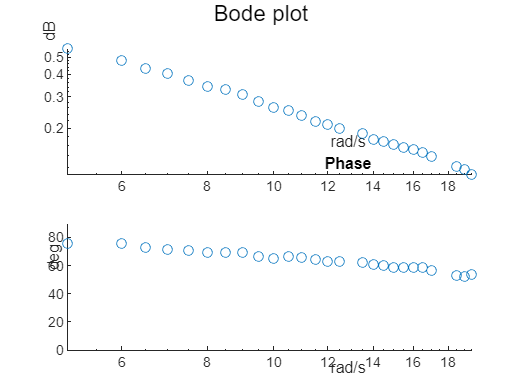

[freqs,phases, gains] = flatten(slices);



figure
sgtitle("Bode plot")
subplot(2,1,1)
scatter(freqs,gains)
yscale("log")
xscale("log")
title("Gain")
xlabel("rad/s")
ylabel("dB")

subplot(2,1,2)
scatter(freqs,rad2deg(phases))
xscale("log")
ylim([0 90])
title("Phase")
xlabel("rad/s")
ylabel("deg")


function idx = time2index(time)
    idx = floor(time/0.002)+1;
end

function [freqs, phases, gain] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    for i = 1:size(slices,2)
        freqs(i) = slices{i}.f;
        phases(i) = slices{i}.phase;
        gain(i) = slices{i}.gain;

    end

end
